## Opgavesæt

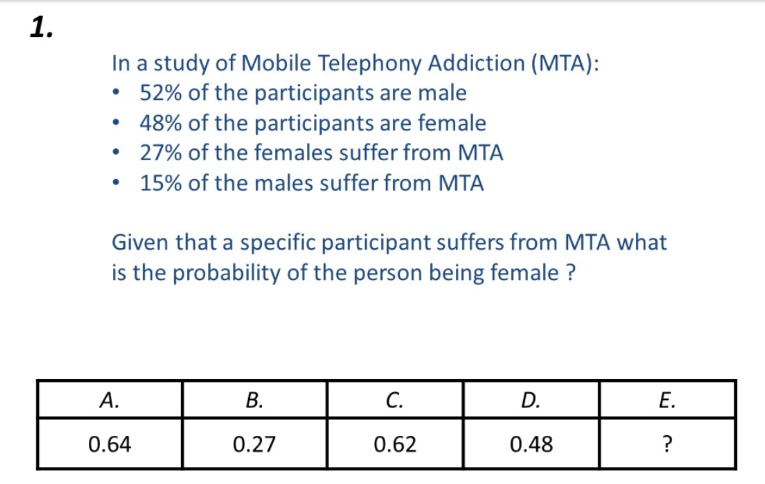

P_A = 0.52; % Mand
P_notA = 0.48; % Kvinde
P_B_notA = 0.27; % Kvinde med MTA
P_B_A = 0.15; % Mand med MTA
P_B = P_B_A*P_A + P_B_notA * P_notA

P_B = 0.2076

P_notA_B = P_B_notA * P_notA / P_B

P_notA_B = 0.6243

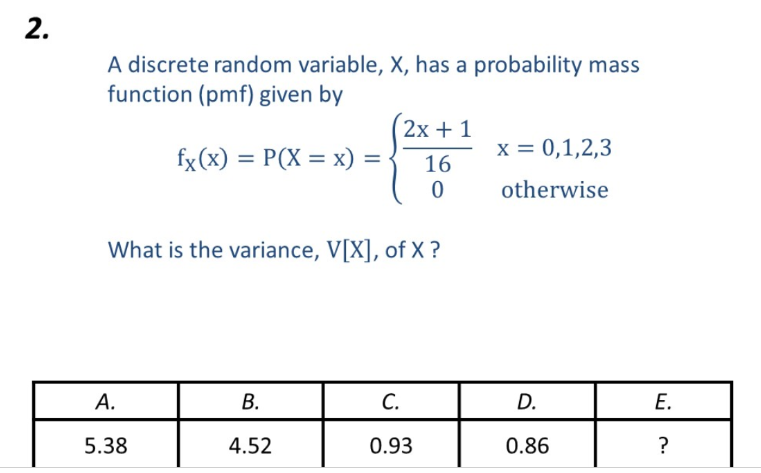

f0 = 0 * (2*0 + 1)/16;
f1 = 1 * (2*1 + 1)/16;
f2 = 2 * (2*2 + 1)/16;
f3 = 3 * (2*3 + 1)/16;
mu_x = f0+f1+f2+f3

mu_x = 2.1250


v0 = (0 - mu_x)^2 * (2 * 0 + 1)/16;
v1 = (1 - mu_x)^2 * (2 * 1 + 1)/16;
v2 = (2 - mu_x)^2 * (2 * 2 + 1)/16;
v3 = (3 - mu_x)^2 * (2 * 3 + 1)/16;
sigma_x = v0+v1+v2+v3

sigma_x = 0.8594

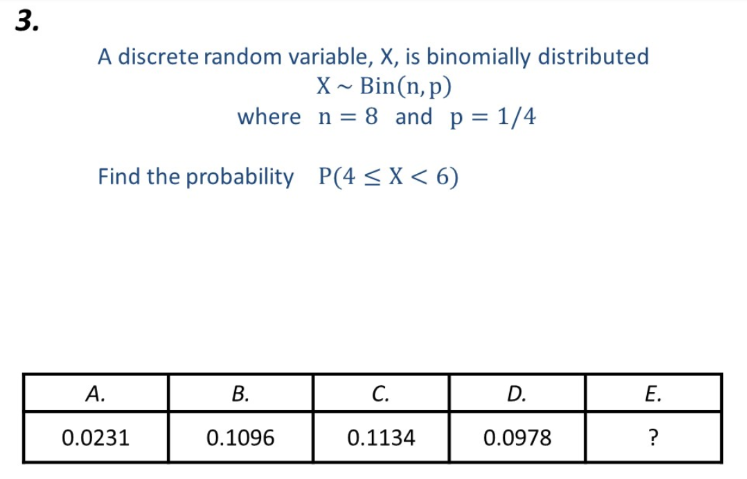

P = binomial_prob(8,0.25,4) + binomial_prob(8,0.25,5)

P = 0.1096

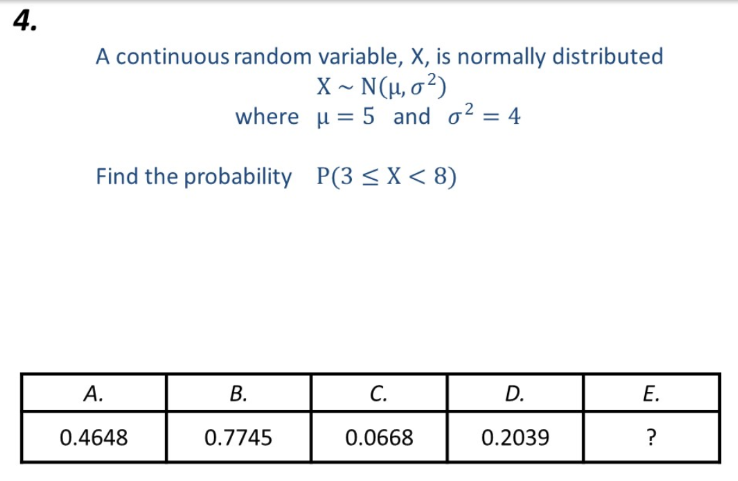

P = normcdf(8,5,sqrt(4)) - normcdf(3,5,sqrt(4))

P = 0.7745

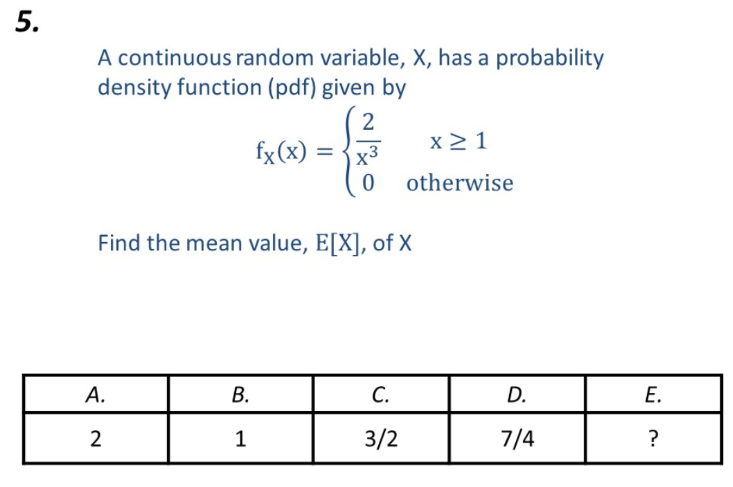

fun = @(x) x*2/(x.^3)

fun = function_handle with value:
    @(x)x*2/(x.^3)


mu_x = integral(fun,1,inf,'ArrayValued',true)

mu_x = 2

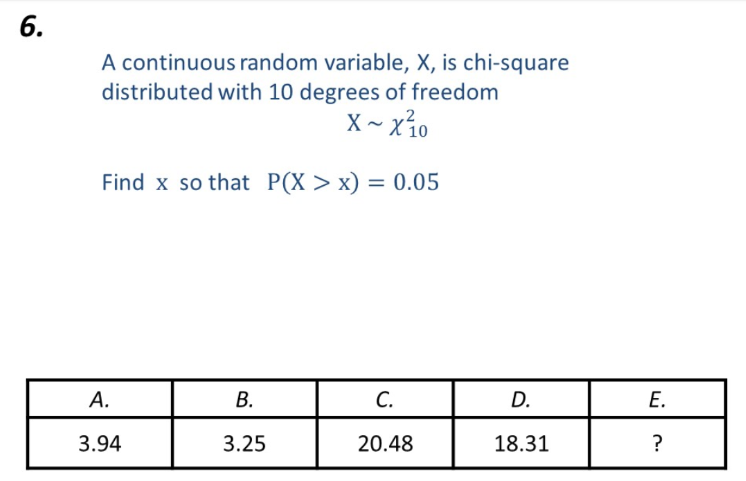

P = 1 - chi2cdf(18.31,10)

P = 0.0500

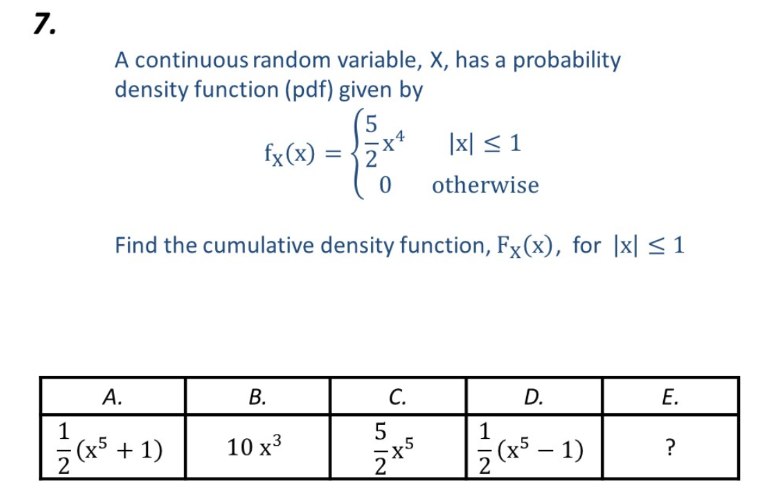

syms x
fun = 5/2 * x^4;
cdf = int(fun)

$$cdf = \frac{x^{5}}{2}$$

int(cdf,-1,1) % Idet dette = 0, må A være det rigtige svar

$$ans = 0$$

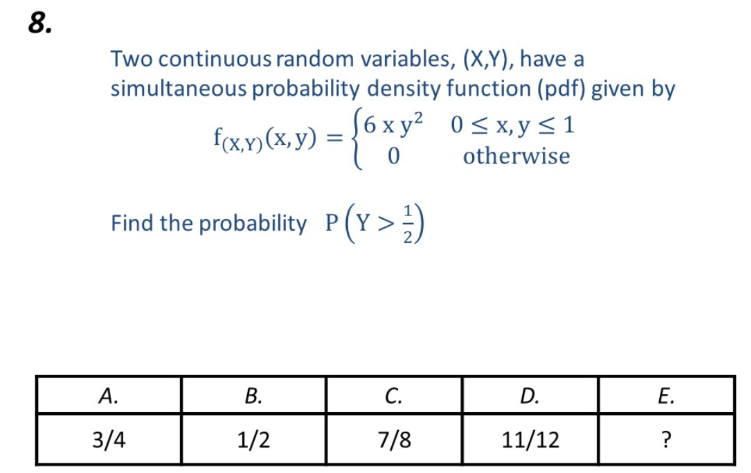

fun = @(x,y) 6.*x.*y.^2;
f_Y = integral2(fun,0,1,0.5,1)

f_Y = 0.8750

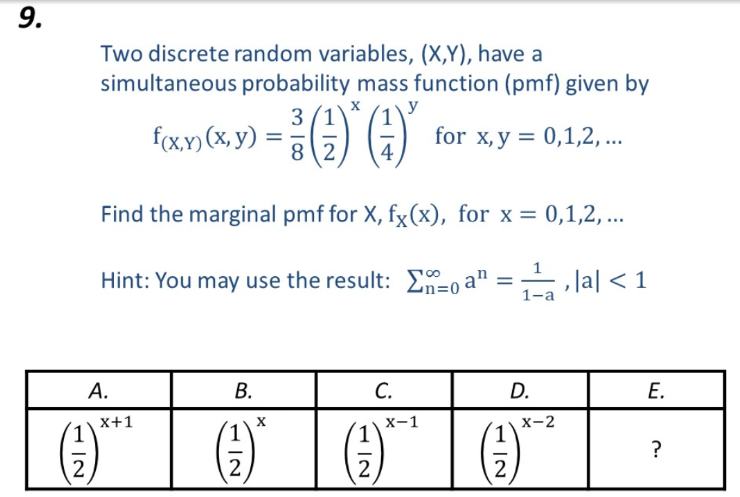

syms x y
f_XY = (3/8) * (1/2)^x * (1/(1-1/4));
int(f_XY,y,-1,1)

$$ans = \frac{1}{2^{x}}$$

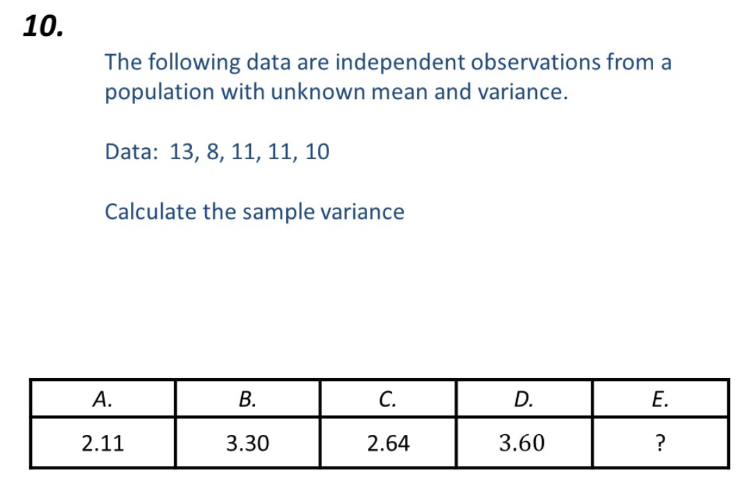

data = [13 8 11 11 10];
sigma_squared = var(data)

sigma_squared = 3.3000

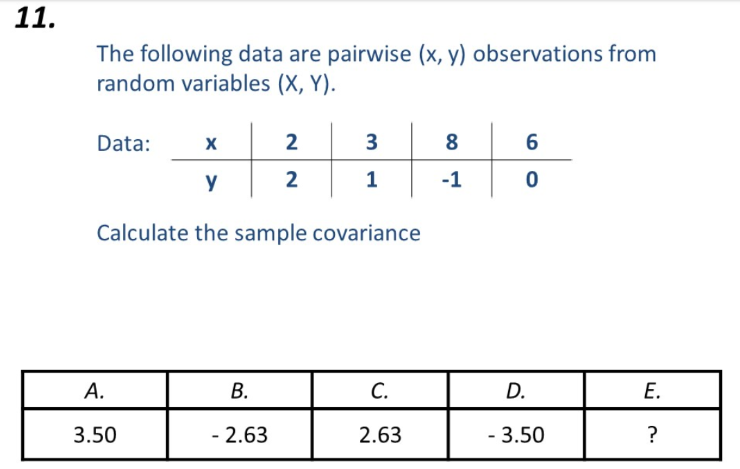

A = [2 3 8 6]

A =      2     3     8     6


B = [2 1 -1 0]

B =      2     1    -1     0


cov(A,B)

ans =     7.5833   -3.5000
   -3.5000    1.6667


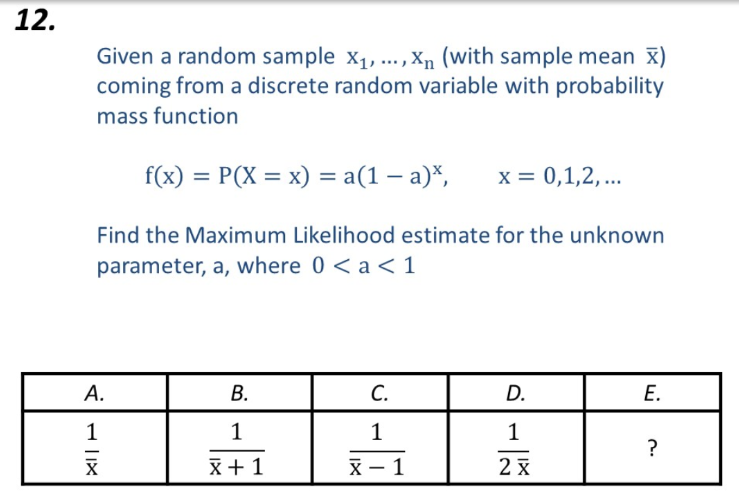

syms x a
f = a*(1-a)^x

$$f = a\,{\left(1-a\right)}^{x}$$

L = prod(f)

$$L = a\,{\left(1-a\right)}^{x}$$

a_hat = solve(diff(log(L),a)==0,a)

$$a\_hat = \frac{1}{x+1}$$

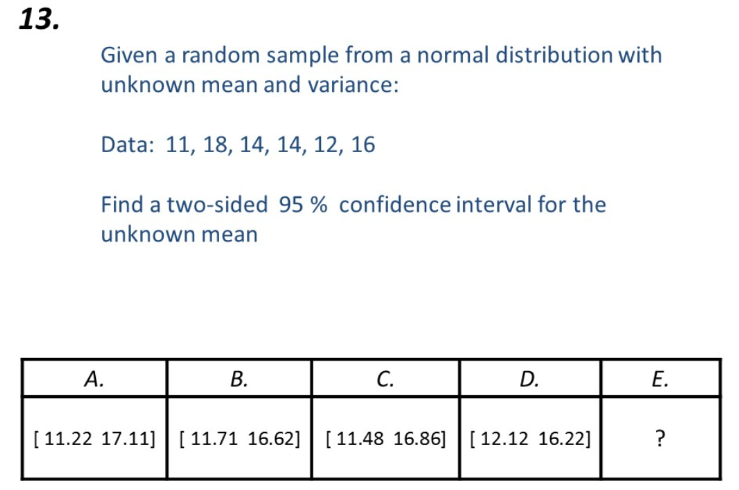

data = [11 18 14 14 12 16];
[H p CI] = ttest(data)

H = 1

p = 3.9346e-05

CI =    11.4774   16.8559


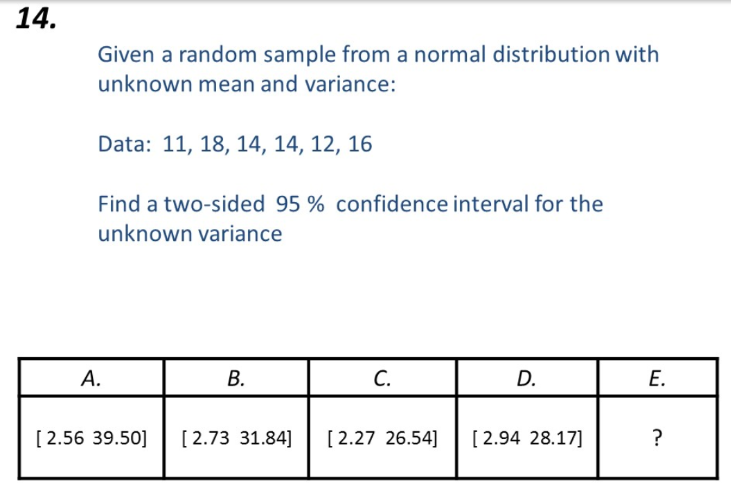

data = [11 18 14 14 12 16];
n = length(data)

n = 6

s_sq = var(data)

s_sq = 6.5667


lo = ((n-1)*s_sq)/chi2inv(1-0.05/2,n-1)

lo = 2.5586

up = ((n-1)*s_sq)/chi2inv(0.05/2,n-1)

up = 39.5006

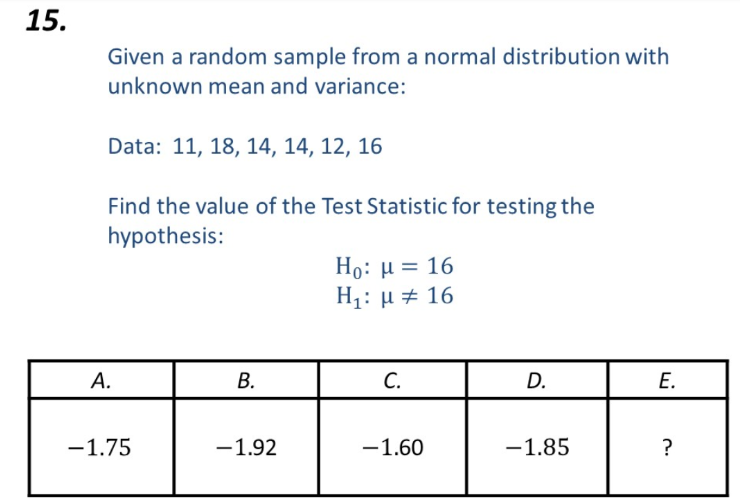

data = [11 18 14 14 12 16];
n = length(data)

n = 6

x_bar = mean(data)

x_bar = 14.1667

s_sq = var(data)

s_sq = 6.5667

s = std(data)

s = 2.5626


t0 = (x_bar-16)/(s/sqrt(n))

t0 = -1.7524

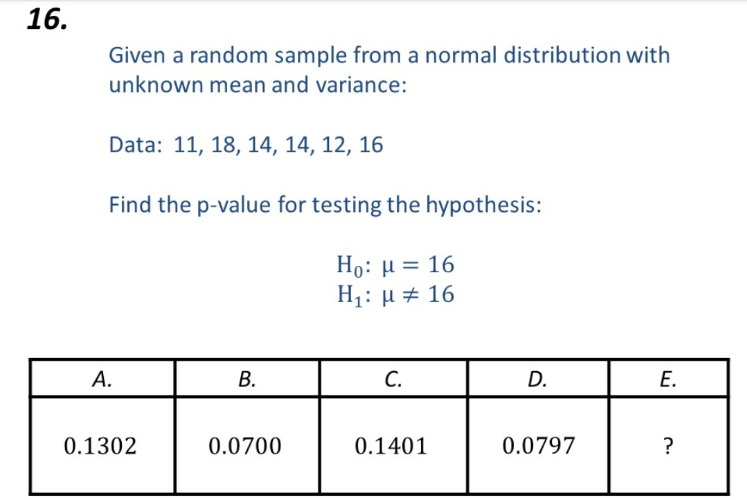

data = [11 18 14 14 12 16];
mu_x = 16;

%p = 2 * (1 - tcdf(abs(t0),n-1))
[H p] = ttest(data,16)

H = 0

p = 0.1401

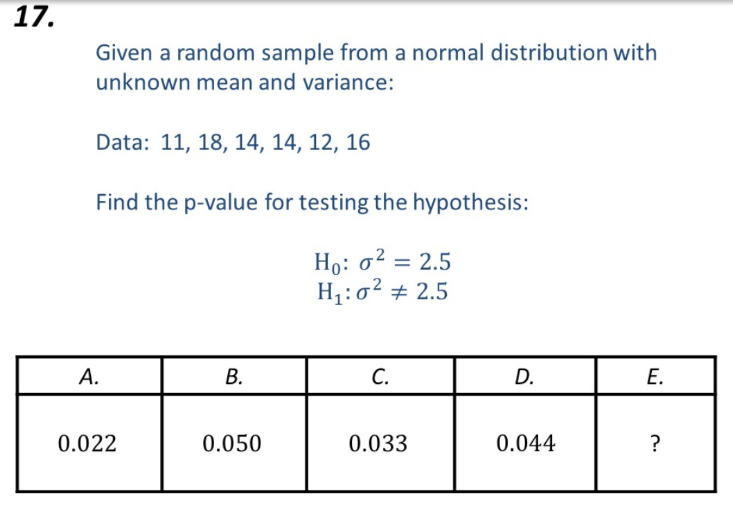

data = [11 18 14 14 12 16];
n = length(data);
s_sq = var(data);

X0 = (n-1)*s_sq/2.5

X0 = 13.1333

p = 2 * (1 - chi2cdf(X0,n-1))

p = 0.0443

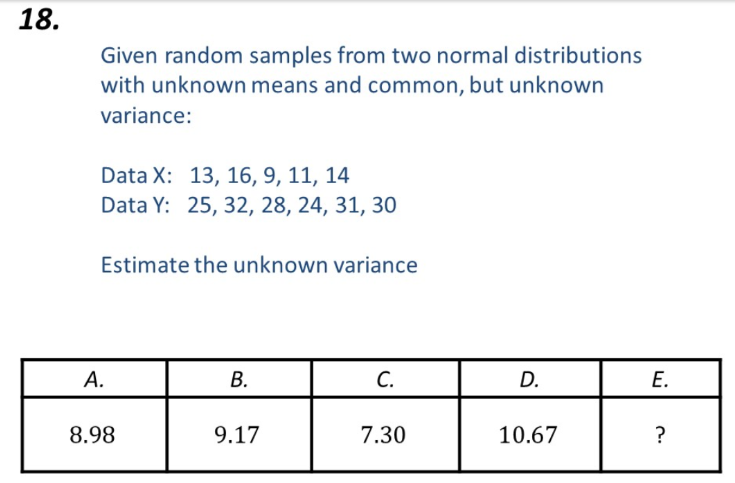

dataX = [13 16 9 11 14]

dataX =     13    16     9    11    14


dataY = [25 32 28 24 31 30]

dataY =     25    32    28    24    31    30


n1 = length(dataX)

n1 = 5

n2 = length(dataY)

n2 = 6

sp = 9.1704

sp = ((n1-1)*var(dataX)+(n2-1)*var(dataY))/(n1+n2-2)

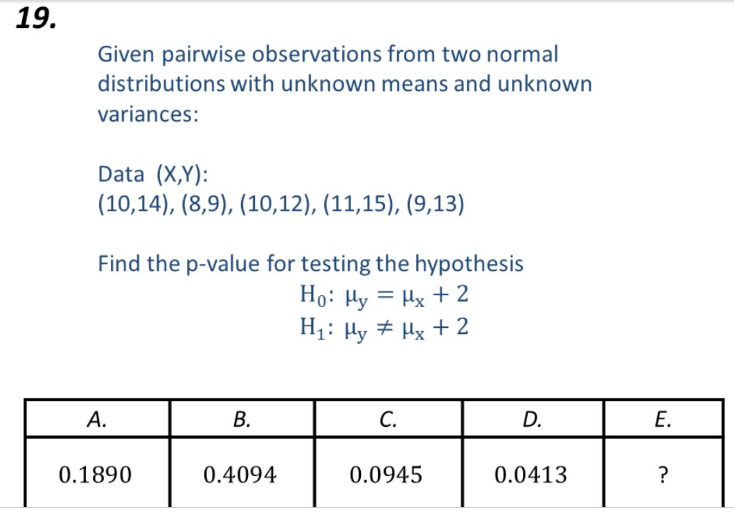

dataX = [10 8 10 11 9];
dataY = [14 9 12 15 13];
%n = length(dataX)
%Dj = dataX-dataY
%D_bar = mean(Dj)
%sd = std(Dj)
%Delta0 = -2;

%t0 = (D_bar-Delta0)/(sd_sq/sqrt(n))
%p = 2 * (1 - tcdf(abs(t0),n-1))

[H, p, stats] = ttest2(dataX+2,dataY)

H = 0

p = 0.4094

stats =    -3.6494    1.6494


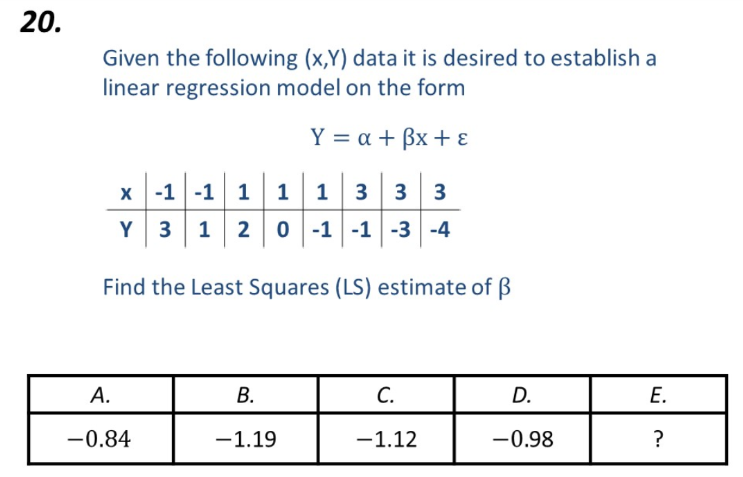

DataX = [-1 -1 1 1 1 3 3 3]';
DataY = [3 1 2 0 -1 -1 -3 -4]';
RegX = [DataX ones(size(DataX))];
[b, bint, r, rint, STATS] = regress(DataY, RegX);
Beta = b(1)

Beta = -1.1923

Alpha = b(2)

Alpha = 1.1154

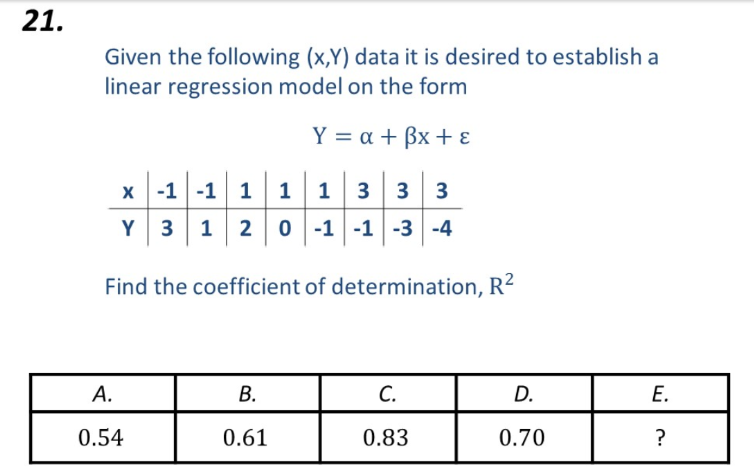

STATS(1)

ans = 0.6952

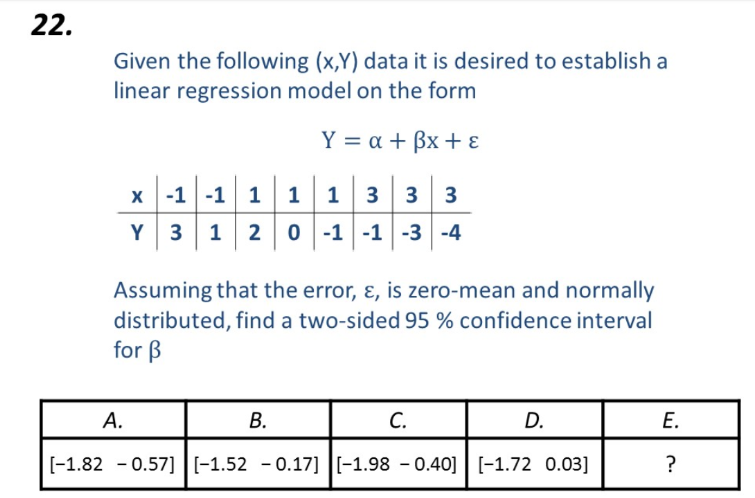

sigma_sq = STATS(4)

sigma_sq = 2.0256

sXX = sum((DataX - mean(DataX)).^2)

sXX = 19.5000


Beta_up = Beta + sqrt(sigma_sq/sXX) * tinv(1-0.05/2,length(DataX)-2)

Beta_up = -0.4037

Beta_do = Beta - sqrt(sigma_sq/sXX) * tinv(1-0.05/2,length(DataX)-2)

Beta_do = -1.9810

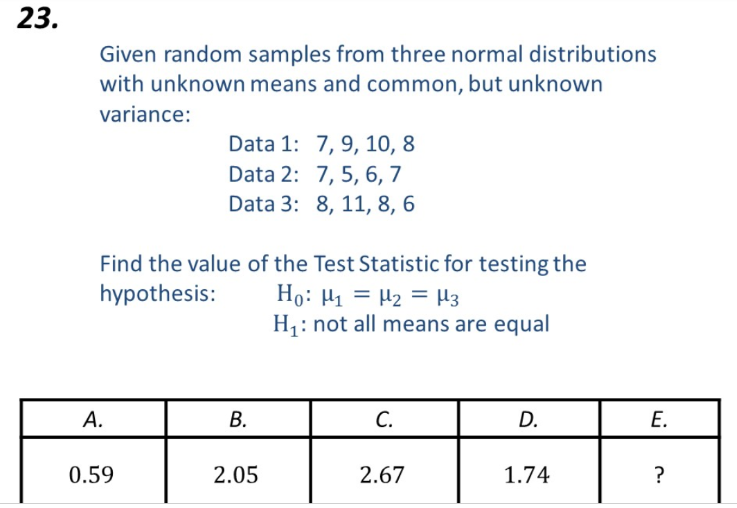

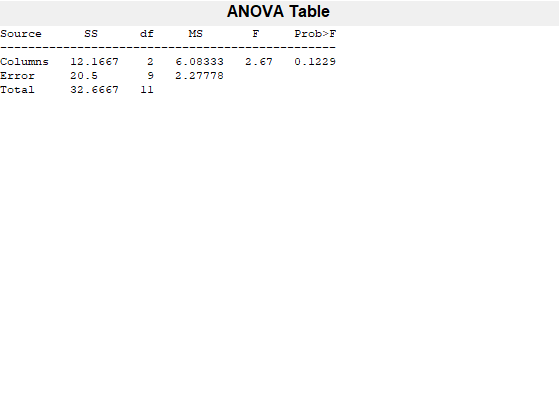

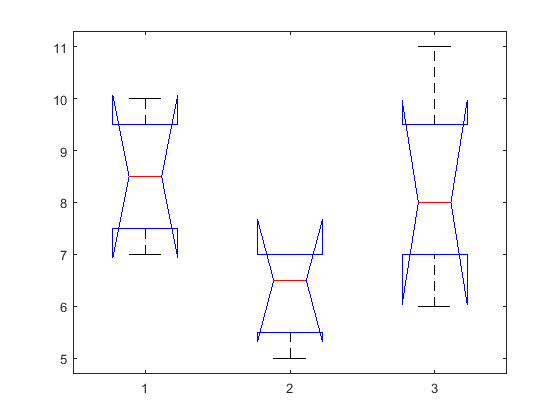

dataX = [7 9 10 8]';
dataY = [7 5 6 7]';
dataZ = [8 11 8 6]';

data = [dataX dataY dataZ];
[p, tbl, stats] = anova1(data);


f0 = tbl{2,4} / tbl{3,4}

f0 = 2.6707

f0 = tbl{2,5}

f0 = 2.6707

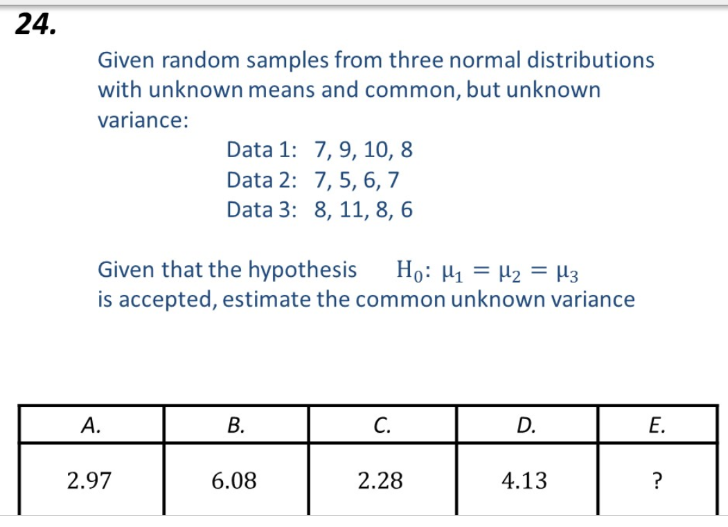

sigma_sq = tbl{4,2} / tbl{4,3}  

sigma_sq = 2.9697

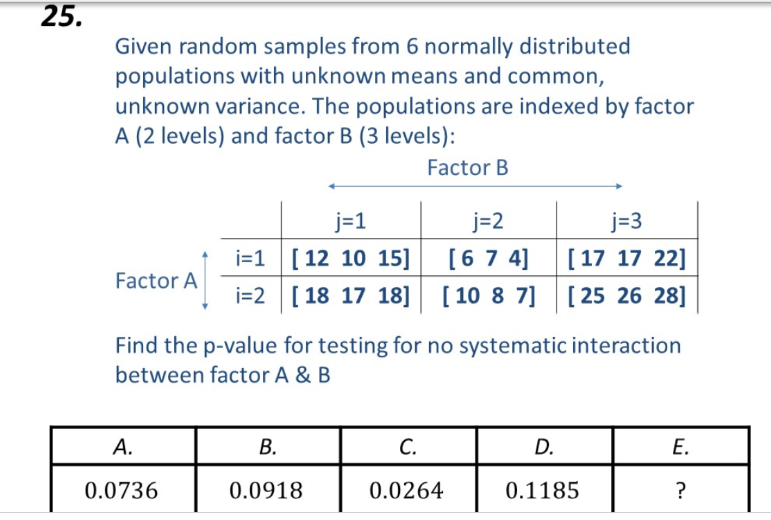

data = [12 6 17
    10 7 17
    15 4 22
    18 10 25
    17 8 26
    18 7 28]

data =     12     6    17
    10     7    17
    15     4    22
    18    10    25
    17     8    26
    18     7    28


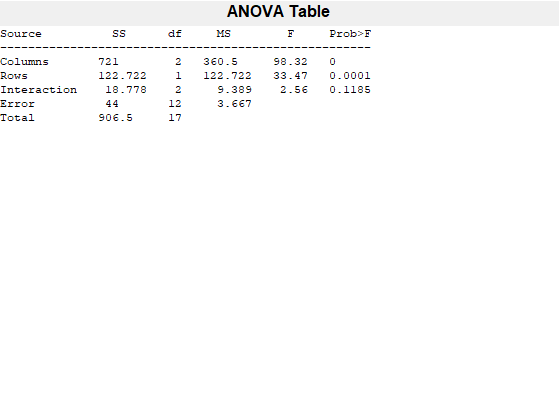

p =     0.0000    0.0001    0.1185


p = anova2(data,3)